# CREATESOM

Create and test a SOM programmatically.

## Load data

load bbstats

## Create variable for SOM

x = statsnorm';  % NNs assume different data organization

## Create an SOM programmatically

Set random seed for reproducibility

rng(1234)
netsize = [8 6];
net = selforgmap(netsize);

## Train on the data

net = train(net,x);

## Visualize the resulting map

Sample hits

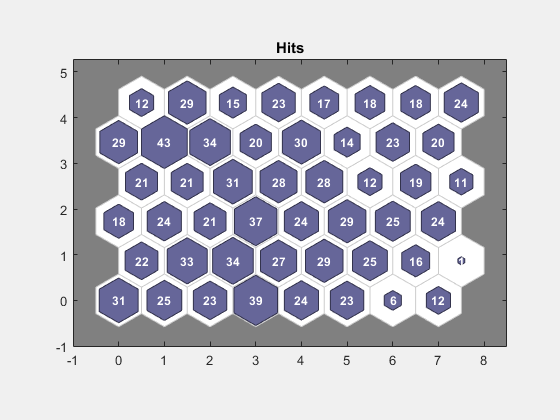

figure
plotsomhits(net,x)

Neighbor distances

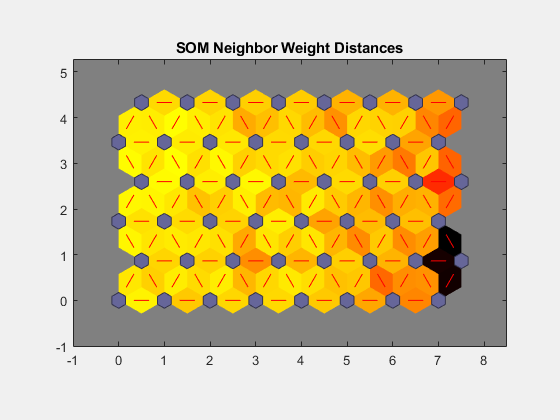

figure
plotsomnd(net)

Weight planes

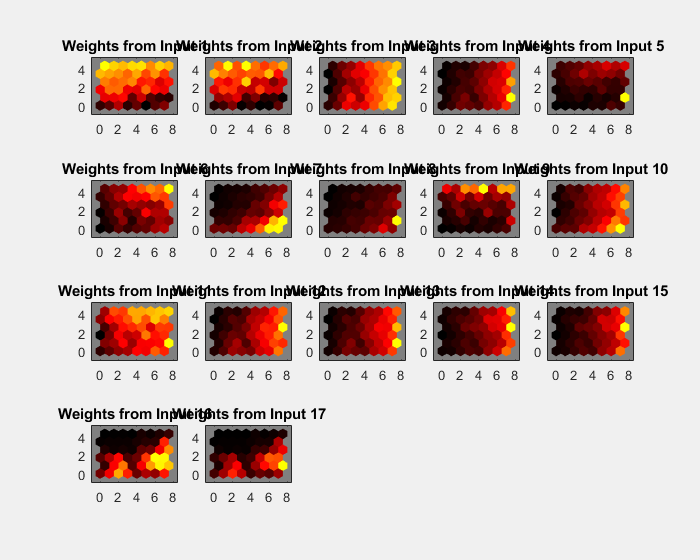

figure
plotsomplanes(net)